`author: Polcz Péter <ppolcz@gmail.com>`

`Created on 2017.03.02. Thursday, 14:14:49`

## Example 1.

Give the state space representation of the following system


$$ y^{(3)} + 6 \ddot y + 11 \dot y + 6 y = 2 \ddot u - 3 \dot u + 6 u $$


Transfer function:

b = [2 -3 6];
a = [1 6 11 6];
H = tf(b,a)


H =
 
     2 s^2 - 3 s + 6
  ----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.



Transform it to state space representation

sys = ss(H)


sys =
 
  A = 
          x1     x2     x3
   x1     -6  -2.75   -1.5
   x2      4      0      0
   x3      0      1      0
 
  B = 
       u1
   x1   2
   x2   0
   x3   0
 
  C = 
           x1      x2      x3
   y1       1  -0.375    0.75
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



A = sys.a;
B = sys.b;
C = sys.c;
D = sys.d;

Compute the Bode diagram of system $H(s)$ using built-in function (angular frequency scale)!

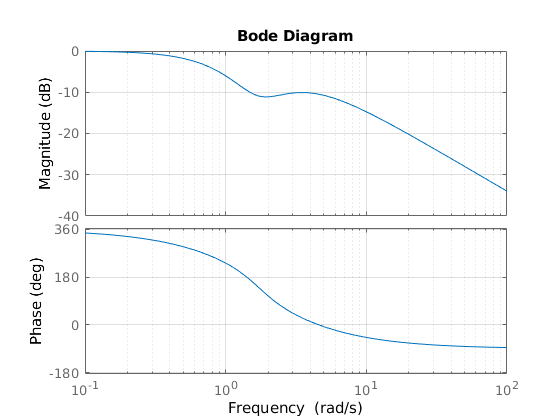

figure, bode(H), grid on

Plot the bode diagram MANUALLY!

- First of all, we compute the transfer function $H(s)$

syms s omega
Hs_sym = poly2sym(b,s) / poly2sym(a,s)

$$Hs\_sym = \frac{2\,s^{2}-3\,s+6}{s^{3}+6\,s^{2}+11\,s+6}$$

- Compute the transfer function in the Fourier (i.e. frequency) domain

Hjw_sym = subs(Hs_sym, s, 1j*omega)

$$Hjw\_sym = -\frac{2\,\omega^{2}+3\,\omega \,\mathrm{i}-6}{-\omega^{3}\,\mathrm{i}-6\,\omega^{2}+11\,\omega \,\mathrm{i}+6}$$

- Generate a function handle

Hjw_fh = matlabFunction(Hjw_sym);

## Linear frequency scale, amplitude on the frequency span between [0,f_max]

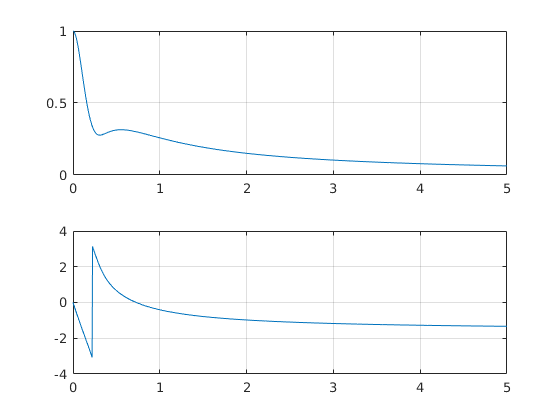

f_max = 5;
f_span = linspace(0,f_max,1000);
w_span = 2*pi*f_span;

amplitude = abs(Hjw_fh(w_span));
phase_shift = angle(Hjw_fh(w_span));

figure,
subplot(211), plot(f_span,amplitude), grid on
subplot(212), plot(f_span,phase_shift), grid on

## Logarithmic frequency scale, magnitude on the frequency span between [0,f_max]

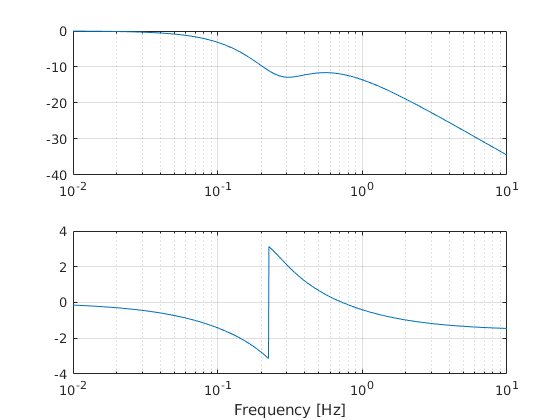

f_max = 10;
f_span = logspace(-2,log10(f_max),1000);
w_span = 2*pi*f_span;

magnitude = 10*log(abs(Hjw_fh(w_span)));
phase_shift = angle(Hjw_fh(w_span));

figure,
subplot(211), semilogx(f_span,magnitude), grid on
subplot(212), semilogx(f_span,phase_shift), grid on
xlabel('Frequency [Hz]')

## Compute the bode diagram of system $H(s)$ using built-in function (frequency scale)!

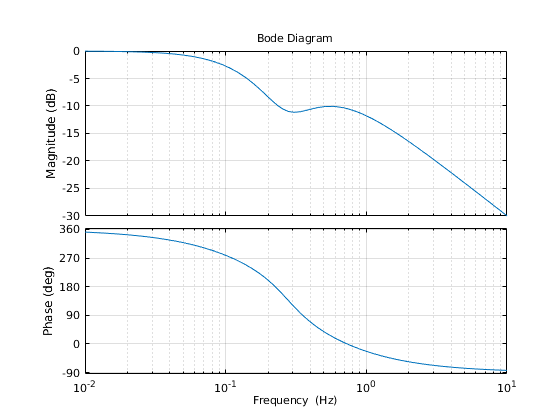

bodeopts = bodeoptions;
bodeopts.FreqUnits = 'Hz';
figure, bodeplot(H,bodeopts), grid on

## Compute the controllability and observability matrix of a SSM

A = [-6 -4 ; 2 0];
B = [4 ; 0];
C = [0  1];

Controllability matrix

Cn = ctrb(A,B)

Cn =      4   -24
     0     8


Cn_by_hand = [B A*B]

Cn_by_hand =      4   -24
     0     8


Rank of matrix $\mathcal C_n$

rank_Cn = rank(Cn)

rank_Cn = 2

Observability matrix

On = obsv(A,C)

On =      0     1
     2     0


On_with_ctrb = ctrb(A',C')'

On_with_ctrb =      0     1
     2     0


On_by_hand = [C ; C*A]

On_by_hand =      0     1
     2     0


Rank of matrix $\mathcal O_n$

rank_On = rank(On)

rank_On = 2

`See also:`

` - obsvf (Observability normal form)`

` - ctrbf (Controllability normal form)`

## Unobservable subspace

Starting the system from any initial condition within the unobservability subspace, the output will be the same.

A = [
    -3  -2  0
    1    0  0
    1    0 -3
    ];

C = [ 1 0 0 ]

C =      1     0     0


O3 = obsv(A,C)

O3 =      1     0     0
    -3    -2     0
     7     6     0


unobsv = null(O3)

unobsv =      0
     0
     1


x0 = rand(3,1)

x0 =     0.7690
    0.3960
    0.2729


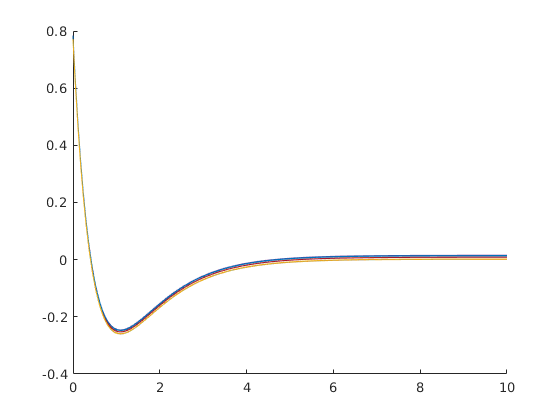


figure, hold on
for i = 1:10
    [t,x] = ode45(@(t,x) A*x, [0, 10], x0 + unobsv*rand(size(unobsv,2),1));
    plot(t,rand*0.02 +(C*x')')
end